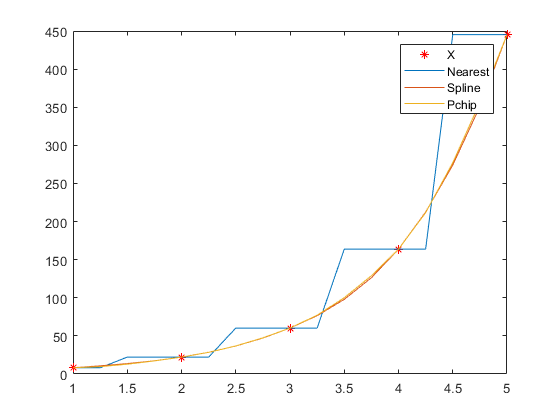

clear variables;

X = 1:5;
xi = 1:.25:5;

Y = 3 * exp(X);                     y1 = 3 * exp(xi);
Y2 = log10(X);                      y2 = log10(xi);
Y3 = polyval([ 1 -2 -3 ], X);       y3 = polyval([ 1 -2 -3], xi);

Y1_i_1 = interp1(X, Y, xi, 'nearest');
Y1_i_2 = spline(X, Y, xi);
Y1_i_3 = pchip(X, Y, xi);

Y2_i_1 = interp1(X, Y2, xi, 'nearest');
Y2_i_2 = spline(X, Y2, xi);
Y2_i_3 = pchip(X, Y2, xi);

Y3_i_1 = interp1(X, Y3, xi, 'nearest');
Y3_i_2 = spline(X, Y3, xi);
Y3_i_3 = pchip(X, Y3, xi);

plot(X, Y, 'r*');
hold on;
plot(xi, Y1_i_1);
plot(xi, Y1_i_2);
plot(xi, Y1_i_3);
legend('X', 'Nearest', 'Spline', 'Pchip');
hold off;

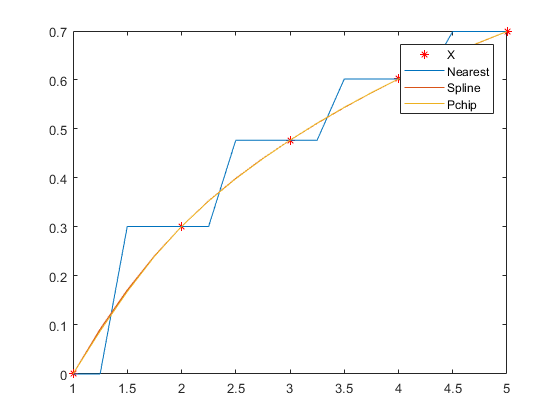


plot(X, Y2, 'r*');
hold on;
plot(xi, Y2_i_1);
plot(xi, Y2_i_2);
plot(xi, Y2_i_3);
legend('X', 'Nearest', 'Spline', 'Pchip');
hold off;

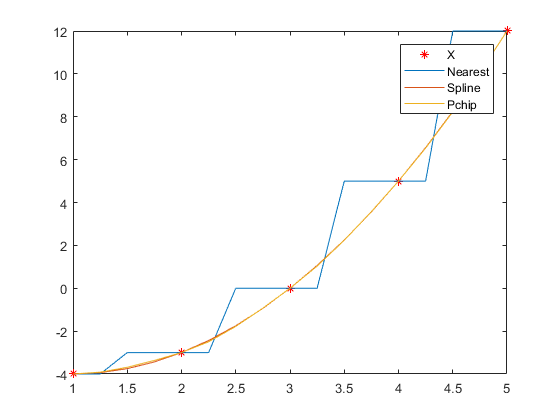


plot(X, Y3, 'r*');
hold on;
plot(xi, Y3_i_1);
plot(xi, Y3_i_2);
plot(xi, Y3_i_3);
legend('X', 'Nearest', 'Spline', 'Pchip');
hold off;

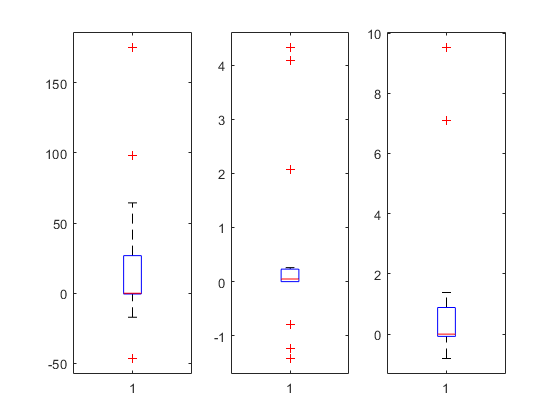

box11 = Y1_i_1 - y1;
box12 = Y1_i_2 - y1;
box13 = Y1_i_3 - y1;

figure(4);
subplot(1, 3, 1);    boxplot(box11);
subplot(1, 3, 2);   boxplot(box12);
subplot(1, 3, 3);   boxplot(box13);

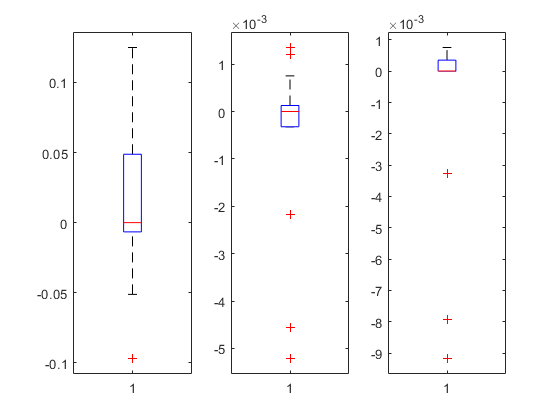

box21 = Y2_i_1 - y2;
box22 = Y2_i_2 - y2;
box23 = Y2_i_3 - y2;

figure(5);
subplot(1, 3, 1);   boxplot(box21);
subplot(1, 3, 2);   boxplot(box22);
subplot(1, 3, 3);   boxplot(box23);

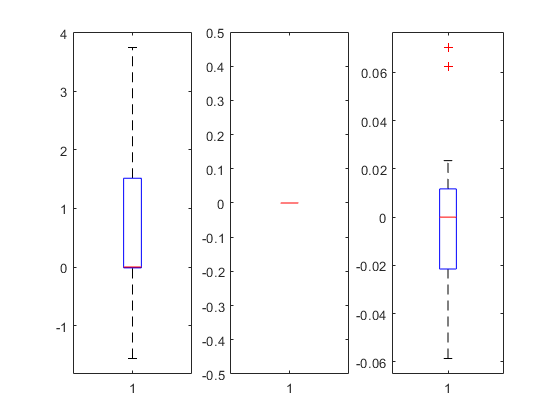

box31 = Y3_i_1 - y3;
box32 = Y3_i_2 - y3;
box33 = Y3_i_3 - y3;

figure(6);
subplot(1, 3, 1);   boxplot(box31);
subplot(1, 3, 2);   boxplot(box32);
subplot(1, 3, 3);   boxplot(box33);